# Illustration of the relationship between the CTFT oand the DFT

### Parameters :

We make sure that the simulated sampling rate answers the **Nyquist condition**

clear; clc; close all;

Omega_max = 10;      
Omega_s = 25;        
Ts = 2*pi / Omega_s; 

Omega = linspace(-3*Omega_s, 3*Omega_s, 2000);

### Continuous signal in Freq. domain :

We take some function of the countinuous freq. domain.

This will simulate the **continuous signal.**

Xc = max(1 - abs(Omega)/Omega_max, 0);


### Sampled signal in Freq. Domain :

We take sum of equal interval samples according to the relationship we have proven in the prelab assignment :


$$X\left(e^{j\omega \;} \right)=\frac{1}{T_s }\sum_{k\in \mathbb{Z}\;} X_c \left(j\left(\frac{\omega }{T_s }-\frac{2\pi k}{T_s }\right)\right)$$


Xs = zeros(size(Omega));
for k = -3:3
    shift = k * Omega_s;
    Xs_k = max(1 - abs(Omega - shift)/Omega_max, 0);
    Xs = Xs + (1/Ts) * Xs_k;
end

### Plotting :

We plot both signals in freq. domain to examine the results.

We can clearly see the said relationship

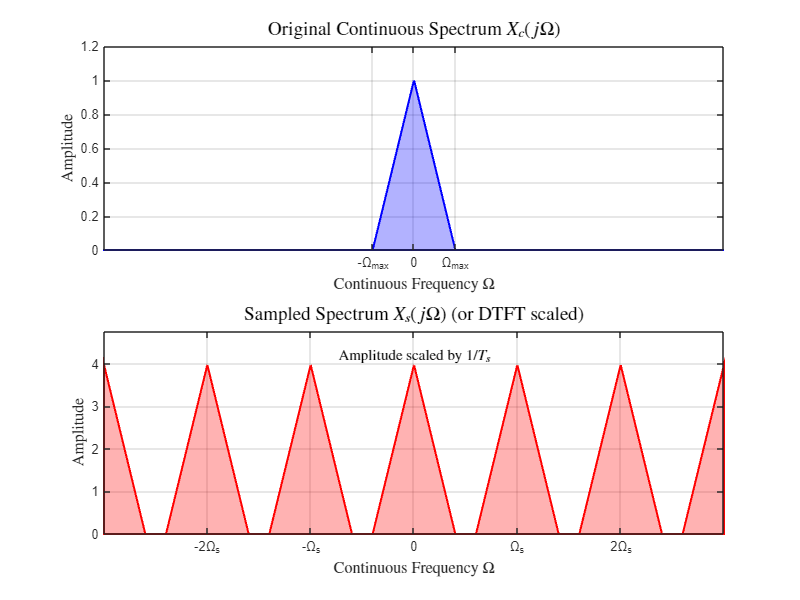

figure('Name', 'Continuous vs Sampled Spectrum', 'Color', 'w', 'Position', [100, 100, 800, 600]);

subplot(2, 1, 1);
fill(Omega, abs(Xc), 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'b', 'LineWidth', 1.5);
title('Original Continuous Spectrum $X_c(j\Omega)$', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Continuous Frequency $\Omega$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Amplitude', 'Interpreter', 'latex', 'FontSize', 12);
grid on;
axis([-3*Omega_s 3*Omega_s 0 1.2]);
xticks([-Omega_max, 0, Omega_max]);
xticklabels({'-\Omega_{max}', '0', '\Omega_{max}'});

% Bottom Graph: Sampled Signal
subplot(2, 1, 2);
% Anchor the ends to y=0
fill([Omega(1), Omega, Omega(end)], [0, Xs, 0], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'r', 'LineWidth', 1.5);title('Sampled Spectrum $X_s(j\Omega)$ (or DTFT scaled)', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Continuous Frequency $\Omega$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Amplitude', 'Interpreter', 'latex', 'FontSize', 12);
grid on;
axis([-3*Omega_s 3*Omega_s 0 (1/Ts)*1.2]);

xticks([-2*Omega_s, -Omega_s, 0, Omega_s, 2*Omega_s]);
xticklabels({'-2\Omega_s', '-\Omega_s', '0', '\Omega_s', '2\Omega_s'});

% Add a text box to highlight the scaling factor
text(0, (1/Ts)*1.05, 'Amplitude scaled by $1/T_s$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 11);